global Deneb

ROCKET; %import rocket geometry

Deneb = struct with fields:
               NAME: "Deneb 2"
    NOSECONE_LENGTH: 0.8799
           DIAMETER: 0.2032
        BODY_LENGTH: 5.6134
                FIN: [1×1 struct]
             ENGINE: [1×1 struct]
       MASS_INITIAL: 127.7771
         MASS_FINAL: 59.7382
              CHUTE: [1×1 struct]
           CD_TRANS: 1.1000


Deneb = struct with fields:
               NAME: "Deneb 2"
    NOSECONE_LENGTH: 0.8799
           DIAMETER: 0.2032
        BODY_LENGTH: 5.6134
                FIN: [1×1 struct]
             ENGINE: [1×1 struct]
       MASS_INITIAL: 127.7771
         MASS_FINAL: 59.7382
              CHUTE: [1×1 struct]
           CD_TRANS: 1.1000


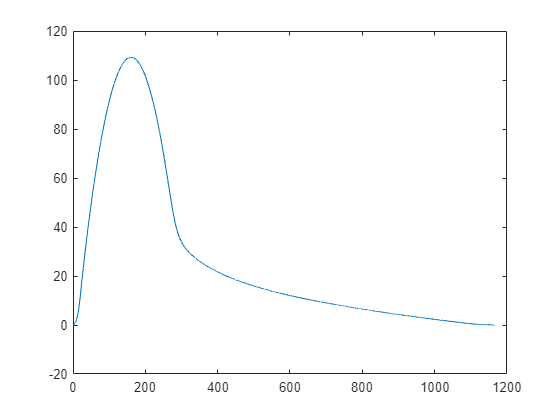


t0 = 0;
tmax = 1000;
dt = 0.1;

g=9.81;

y0 = 0;
v0 = 0;
mdot0 = Deneb.ENGINE.MDOT_0;
m0 = Deneb.MASS_INITIAL;

time = t0:dt:tmax;

optionsPowered = odeset('Events', @eventsPowered);
[T_Powered, S_Powered] = ode45(@(t,s) eomPowered(t,s,g,Deneb), time, [y0, v0, m0], optionsPowered);

optionsBallistic = odeset('Events', @eventsBallistic);
[T_Ballistic, S_Ballistic] = ode45(@(t,s) eomBallistic(t,s,g,Deneb.MASS_FINAL,Deneb), time, [S_Powered(end,1), S_Powered(end,2)], optionsBallistic);

optionsDrogue = odeset('Events', @(t,s) eventsParachute(t,s,300));
[T_Drogue, S_Drogue] = ode45(@(t,s) eomParachute(t,s,g,Deneb.MASS_FINAL,Deneb.CHUTE.AREA_DROGUE,Deneb.CHUTE.CD_DROGUE), time, [S_Ballistic(end,1), S_Ballistic(end,2)], optionsDrogue);

optionsMain = odeset('Events', @(t,s) eventsParachute(t,s,0));
[T_Main, S_Main] = ode45(@(t,s) eomParachute(t,s,g,Deneb.MASS_FINAL,Deneb.CHUTE.AREA_MAIN,Deneb.CHUTE.CD_MAIN), time, [S_Drogue(end,1), S_Drogue(end,2)], optionsMain);



T = [T_Powered; T_Ballistic+T_Powered(end); T_Drogue+T_Powered(end)+T_Ballistic(end);T_Main+T_Drogue(end)+T_Powered(end)+T_Ballistic(end)];
S = [S_Powered(:,1:2); S_Ballistic; S_Drogue; S_Main];
figure
plot(T, S(:,1)/1000)


% maxes = [0, 0, 0];
% for i=1:length(S)
%     v = S(i,2);
%     h = S(i,1);
%     [T_, a, P, rho] = atmosisa(h, extended=true, action="none");
%     Fd = Drag(Cd, refA, rho, v);
%     if Fd > maxes(1)
%         maxes(1) = Fd;
%         maxes(2) = v / a;
%         maxes(3) = h;
%     end
% end
% sprintf("Max drag force: %d N, mach at point: %.3d, altitude at point: %d m", maxes)

function sdot = eomPowered(t,s,g,Deneb)
    h = s(1);    
    v = s(2);
    mass = s(3);
    [~, a, P, rho] = atmosisa(h, "extended","on", "action","None");
    [Ft, mdot, ~, ~] = Engine(t, P, Deneb);
    if v/a > Deneb.LIM_TRANS
        [Fd, P] = SonicSkinDrag(h, v, Deneb);
    elseif v/a <=Deneb.LIM_TRANS || v/a >= .8
        Fd = .5*Deneb.CD_TRANS*Deneb.DIAMETER^2/4*pi*rho*v^2;
    else
        Fd = SubSonicSkinDrag(h, v, Deneb);
    end
    Fd = Fd+PressureDrag(P, h, Deneb);
    sdot(1,1) = v;
    sdot(2,1) = (Ft - Fd)/mass - g;
    sdot(3,1) = -mdot;
end

function sdot = eomBallistic(t,s,g,m,Deneb);
    h = s(1);    
    v = s(2);
    [~, a, P, rho] = atmosisa(h, "extended","on", "action","None");
    if v/a > Deneb.LIM_TRANS
        [Fd, P] = SonicSkinDrag(h, v, Deneb);
    elseif v/a <=Deneb.LIM_TRANS || v/a >= .8
        Fd = .5*Deneb.CD_TRANS*Deneb.DIAMETER^2/4*pi*rho*v^2;
    else
        Fd = SubSonicSkinDrag(h, v, Deneb);
    end
    Fd = Fd+PressureDrag(P, h, Deneb);
    sdot(1,1) = v;
    sdot(2,1) = -(Fd/m + g);
end

function sdot = eomParachute(t,s,g,m,area,cd);
    h = s(1);    
    v = s(2);
    [~, ~, P, rho] = atmosisa(h, "extended","on", "action","None");
    Fd = 1/2*area*cd*rho*v^2;
    sdot(1,1) = v;
    sdot(2,1) = Fd/m - g ;
end

function [value, isterminal, direction] = eventsPowered(t, s)
    global Deneb
    value = s(3) - Deneb.MASS_FINAL;
    isterminal = 1;
    direction = 0;
end

function [value, isterminal, direction] = eventsBallistic(t, s)
    value = s(2);
    isterminal = 1;
    direction = 0;
end

function [value, isterminal, direction] = eventsParachute(t, s, stop)
    value = s(1)-stop;
    isterminal = 1;
    direction = 0;
end